# シリアル通信による通信頻度の計測

PC-SH2でのシリアル通信において最短の通信頻度を計測する．

計測方法としては，次の手順を繰り返すことで実現する．

- PCからSH2にデータ要求命令を送信する．

- SH2からのデータが送られてくるのを待機

- SH2からデータが送られてき次第1.に戻る

これを複数回繰り返したのち，SH2から送られてきたデータの中にあるタイムスタンプの差分をとることで2つのデータ間のインターバルを計測する．

最終的にヒストグラムにプロットすることでおおよその通信頻度を計算する．

## 実験パラメータの設定

clear all;

SAMPLE_NUM = 100;  % 1サンプルの頻度は20[ms]程度であることを予備実験で確認

## データのサンプル

### デバイスへの接続

serialList = serialportlist;
if size(serialList) == 1
    s = serialport(serialList(1), 57600, "byteOrder", "big-endian", "Timeout", 0.1);
else
    disp('Error: 複数のシリアルデバイスが接続されています');
end

### データのサンプリング

for i = 1 : SAMPLE_NUM
    write(s, 0, "double");  % おそらくビッグエンディアンで送信を行っている．

%     sci_read(s);
%     sci_read_with_decode(s)
    sh2pc(i) = sci_read_with_decode_using_checksum(s);
    
end

### デバイスの切断

デバイスを切断する

write(s, 0, "double");
clear s;

## 実験結果のプロット

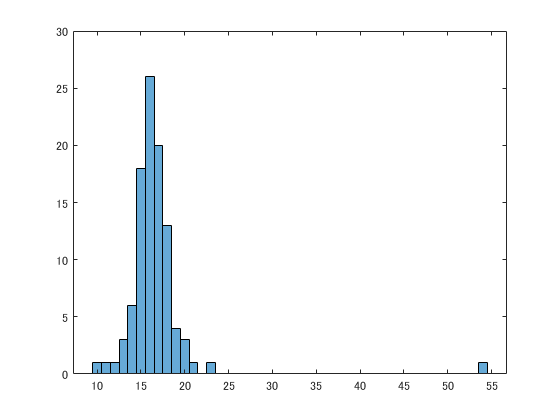

sh2pc = struct2table(sh2pc);
histogram(sh2pc.TMStamp(2:end) - sh2pc.TMStamp(1:end-1));

max(sh2pc.TMStamp(2:end) - sh2pc.TMStamp(1:end-1))

ans = int64
54

min(sh2pc.TMStamp(2:end) - sh2pc.TMStamp(1:end-1))

ans = int64
10